### Setup

% Clear the workspace
clear all; close all; clc

% Select three distinct colors
co = lines(3);  

% Simulation time vector
t = 0:0.002:30;

% Number of initial conditions
nCond = 3;
Nt    = numel(t);

% Preallocation 
h_MF      = zeros(Nt, nCond);  % without observer
h_OBS0    = zeros(Nt, nCond);  % observer with x_hat(0) = 0
h_OBSinit = zeros(Nt, nCond);  % observer with well-initialized x_hat(0)

### Linearized System

A = [ -0.6 -0.76 0    0; 
      1    0     0    0; 
      0    102.4 -0.4 0; 
      0    0     1    0 ];

B = [ -2.375; 0; 0; 0 ];

C = [ 1 0 0 0; 
      0 1 0 0; 
      0 0 0 1 ];

D = 0;

sys= ss(A,B,C,D);

### Checking Controllability

rankCo = rank(ctrb(A, B)) % Fully controllable

rankCo = 4

### 1) Computing the LQR Gain Vector K

Q = diag([1.6^2 1.6^2 1e-4 1e-5]);
R = 1;
K=lqr(A,B,Q,R)

K =    -1.8690   -2.2294   -0.0088   -0.0032


### 2) Landing Response for Different Initial Conditions

Given the system


$$\dot{x} =\textrm{Ax}+\textrm{Bu}$$


given that


$$u={-K}_1 x_1 {\;-K}_2 x_{2\;} \;{-K}_3 x_3 \;{-K}_4 x_4 +K_3 \dot{h_d } +K_4 h_d \;$$


it can be rewritten as:


$$u=-\textrm{Kx}+K_r r$$


where,


$$K=\left\lbrack \begin{array}{cccc}
K_1  & K_2  & K_3  & K_4 
\end{array}\right\rbrack ,{\;\;\;\;\;\;K}_r =\left\lbrack \begin{array}{cc}
K_3  & K_4 
\end{array}\right\rbrack$$


and the reference $r:$


$$r=\left\lbrack \begin{array}{c}
\dot{\left\lbrack h_d \right\rbrack } \\
h_d 
\end{array}\right\rbrack$$


the closed-loop dynamics are:


$$\dot{x} =\textrm{Ax}+B\left(-\textrm{Kx}+K_r r\right)$$



$$\dot{x} =\left(A-\textrm{BK}\right)x+\left({\textrm{BK}}_r \right)r$$


Kr = [K(3) K(4)];

% Define the controlled system
SYS_MF = ss(A-B*K, B*Kr, C, D);

% Reference h_d(t)
seg = t <= 15;
hd       = 100*exp(-t/5);
hd(~seg) = 20 - t(~seg); 

% Reference \dot{hd}(t)
hdot = gradient(hd, t);

% Reference signal r
r = [hdot.'  hd.'];

% Initial conditions
X0 = [ 0, asin(-16/256), -16, 120;
       0, asin(-20/256), -20, 100;
       0, asin(-24/256), -24, 80 ];

% Plot signals
f = figure(1);
set(f, 'Visible', 'on')
hold off;
set(f, 'Units', 'normalized');
set(f, 'Position', [0  0  0.2  1]);

subplot(3,1,1);
hold on; grid on;


for i = 1:3
    Y_MF = lsim(SYS_MF, r, t, X0(i,:)); 
    h_MF(:,i) = Y_MF(:,3);

    plot(t, h_MF(:,i), 'LineWidth', 1.5);
end

% Plot the altitude reference
plot(t, r(:,2), 'k--', 'LineWidth', 2);

ylim([-20 130]);

xlabel('Time [s]');
ylabel('Altitude [ft]');
legend('h(t) X0_1','h(t) X0_2','h(t) X0_3','Reference (r)','Location','Best');
title('Without Observer')

### 3) Reduced-Order Observer

To build the reduced-order observer, a similarity transformation is used to place the system in the form:


$$\left\lbrack \begin{array}{c}
\dot{x_m } \\
\dot{x_d } 
\end{array}\right\rbrack =\underset{A_{\textrm{new}} }{\underbrace{\left\lbrack \begin{array}{cc}
A_m  & A_{12} \\
A_{21}  & A_d 
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x_m \\
x_d 
\end{array}\right\rbrack +\underset{B_{\textrm{new}} }{\underbrace{\left\lbrack \begin{array}{c}
B_m \\
B_d 
\end{array}\right\rbrack } } u$$



$$y=\underset{C_{\textrm{new}} }{\underbrace{\left\lbrack \begin{array}{cc}
I & 0
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x_m \\
x_d 
\end{array}\right\rbrack$$


This requires a transformation matrix $T$ to reorder the states so that


$$x_{\textrm{new}} ={\left\lbrack \begin{array}{cc}
x_m  & x_d 
\end{array}\right\rbrack }^T \;\;\;\;\;\longrightarrow \;\;\;\;\;x_{\textrm{new}} ={\left\lbrack \begin{array}{cccc}
x_1  & x_2  & x_4  & x_3 
\end{array}\right\rbrack }^T$$


- $x_m =$ Measured states

- $x_d =$ Unmeasured states

then, the transformed system is:


$$A_{\textrm{new}} =\textrm{TA}T^{-1} ,\;\;\;B_{\textrm{new}} =\textrm{TB},\;\;C_{\textrm{new}} =CT^{-1}$$


choosing T as:


$$T=\left\lbrack \begin{array}{c}
C\\
\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0
\end{array}\right\rbrack 
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 1 & 0
\end{array}\right\rbrack$$


% Reorder into measured + unmeasured states
T = [C;[0 0 1 0]];
%T = [C;randn(1,4)]
ss_new = ss2ss(sys,T);

% Split the matrices (Am, A12, A21, Ad)
[n,m] = size(B);
[p,~] = size(C);

Am  = ss_new.A(1:p,1:p); 
A12 = ss_new.A(1:p,p+1:n);
A21 = ss_new.A(p+1:n,1:p); 
Ad  = ss_new.A(p+1:n,p+1:n);
Bm  = ss_new.B(1:p,1:m);
Bd  = ss_new.B(p+1:n,1:m);

The expression for the measured state is:


$$
\[
\begin{array}{|c|}
\hline
\qquad \dot{x_m } =A_m x_m +A_{12} x_d +B_m u \qquad \\[2pt]
\hline
\end{array}
\]
$$


however, note that:


$$y=\underset{C_{\textrm{new}} }{\underbrace{\left\lbrack \begin{array}{cc}
I & 0
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x_m \\
x_d 
\end{array}\right\rbrack \;\;\;\;\;\longrightarrow \;\;\;\;y=x_m ,\;\;\;\textrm{logo}\;\;\;\;\dot{y} =\dot{x_m }$$


and therefore:


$$\bar{y} =A_{12} x_d$$



$$\bar{y} =\dot{y} \;-A_m y-B_m u$$


the expression for the unmeasured state is


$$
\[
\begin{array}{|c|}
\hline
\qquad \dot{x_d } =A_{21} x_m +A_d x_d +B_d u \qquad \\[2pt]
\hline
\end{array}
\]
$$


which can be rewritten as:


$$\dot{x_d } =A_d x_d +\bar{u}$$



$$\bar{u} =A_{21} x_m +B_d u$$


from the manipulations above, the system becomes


$$\begin{array}{l}
\dot{x_d } =A_d x_d +\bar{u} \\
\bar{y} =A_{12} x_d 
\end{array}$$


which has the form required for a full-order observer, therefore:


$$\dot{\hat{x_d } } =A_d \hat{x_d } +\bar{u\;} +L\left(\bar{y} -C\hat{x_d } \right)$$


expanding:


$$
\[
\begin{array}{|c|}
\hline
\qquad \dot{\hat{x_d } } =\left(A_d -{\mathrm{LA}}_{12} \right)\hat{x_d } +(A_{21}-LA_m)y+(B_d-LB_m)u\qquad \\[2pt]
\hline
\end{array}
\]
$$


it is clear that the problem reduces to pole placement for $A_d -{\textrm{LA}}_{12}$:

poles = eig(SYS_MF) % Dominant pole = -0.2916

poles =   -3.4752 + 0.0000i
  -0.8360 + 0.2451i
  -0.8360 - 0.2451i
  -0.2916 + 0.0000i



% Place the observer pole at least 2x faster than the dominant pole
[L]=(place(Ad',A12', -0.6));
L=L'

L =          0         0    0.2000


### 4) Closed-Loop Response with Observer

writing the system in matrix form:


$$\left\lbrack \begin{array}{c}
\dot{x_m } \\
\dot{x_d } \\
\dot{\hat{x_d } } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A_m  & A_{12}  & 0\\
A_{21}  & A_d  & 0\\
A_{21}  & LA_{12}  & A_d -LA_{12} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_m \\
x_d \\
\hat{x_d } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B_m \\
B_d \\
B_d 
\end{array}\right\rbrack u$$


Atot=[ Am  A12   zeros(p,n-p);
       A21 Ad    zeros(n-p,n-p);
       A21 L*A12 Ad-L*A12 ];
Btot=[ Bm; Bd; Bd ];
Ctot=T\[eye(p) zeros(p,n-p) zeros(p,n-p);zeros(n-p,p) zeros(n-p,n-p) eye(n-p)]; % identity matrix
Dtot= 0;
ss2_completo=ss(Atot,Btot,Ctot,Dtot);

Ttot = [T zeros(n,n-p); zeros(n-p,n) eye(n-p)];

% Final system - open loop
SYS_F_OL = ss2ss(ss2_completo, inv(Ttot));

% Final system - closed loop
SYS_F_CL = ss([SYS_F_OL.A - SYS_F_OL.B * K * SYS_F_OL.C], ...
             [SYS_F_OL.B * Kr], [SYS_F_OL.C], 0);


A deviation can be observed between the altitude curves of the system without observer and the system with the observer initialized at $x_0 =0$. This error is a direct consequence of the observer initial estimation error. 

In the original state-feedback system, the control law uses the real state vector $x\left(t\right)$. In the reduced-order observer system, the law uses a state estimate, specifically the estimate of the unmeasured state $x_{3\left(\right.} \left(t\right)$. Since the observer is initialized with $x_3 \left(0\right)=0$, while in reality $x_3 \left(0\right)\;\not= 0$ for the considered initial conditions, an initial estimation error is introduced.

Thus, the error observed in the plot is the transient effect of the estimation error. As the observer converges, this error vanishes and the observer-based response approaches the ideal full-state feedback response.

% Plot
subplot(3,1,2);
hold on; grid on;

% Plot signals
for i = 1:3
    Y_OBS0 = lsim(SYS_F_CL, r, t, [X0(i,:), 0]); 
    h_OBS0(:,i) = Y_OBS0(:,4);

    plot(t, h_OBS0(:,i), 'LineWidth', 1.5);
end

% Plot the reference
plot(t, r(:,2), 'k--', 'LineWidth', 2);

ylim([-20 130]);

xlabel('Time [s]');
ylabel('Altitude [ft]');
legend('h(t) X0_1','h(t) X0_2','h(t) X0_3','Reference (r)','Location','Best');
title('With Observer (X_0 = 0)')

### 5) Observer Initialization Discussion

In practice, initializing the observer with a zero initial condition introduces an error:


$$e\left(0\right)=x_3 \left(0\right)-\hat{x_3 } \left(0\right)$$


For example, in the case where $x_3 \left(0\right)=-20$, we have:


$$e\left(0\right)=-20-0=-20\;\textrm{ft}/s$$


this error directly affects the control law:


$$u=-K_1 x_1 -K_2 x_2 -K_3 \left(\hat{x_3 } -\dot{h_d } \right)-K_4 \left(x_4 -h_d \right)$$


In a real implementation, this can create sharper initial control-surface commands, possible actuator saturation, acceleration peaks, and, in extreme cases, violations of safety envelopes.

Therefore, real applications try to initialize the observer as close as possible to the real state. In this case, one way to estimate the initial state is to use the relationships among the variables. From the assignment statement:


$$\Delta \theta_0 =\frac{0\ldotp 4}{102\ldotp 4}\dot{h_o } \;\;\;\;\;\;\longrightarrow \;\;\;\dot{h_o } =256\;\Delta \theta_0 \;$$


therefore, one way to initialize $\hat{x_3 } \left(0\right)$ is:


$$\hat{x_3 } \left(0\right)=256{\cdot \;x}_2 \left(0\right)$$


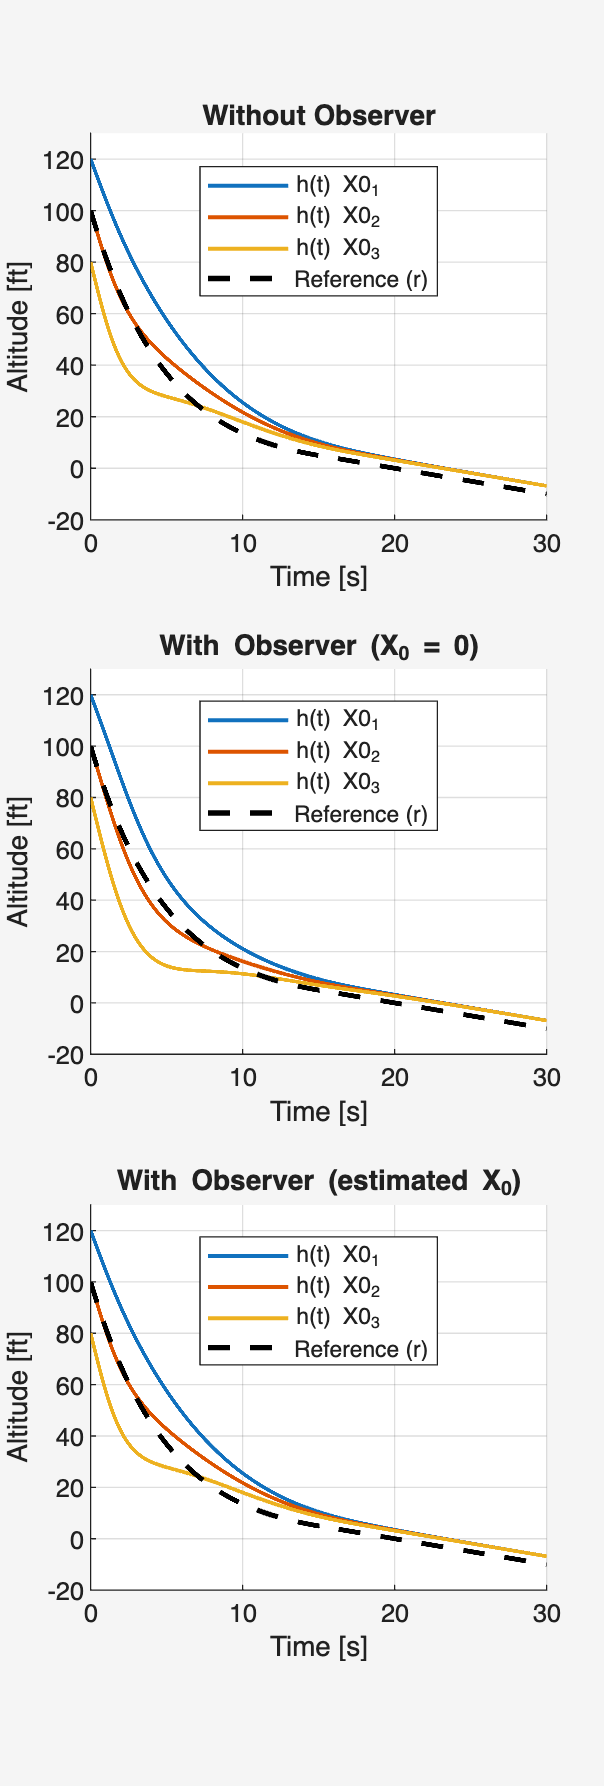

% Plot
subplot(3,1,3);
hold on; grid on;


% Plot signals
for i = 1:3
    Y_OBSinit = lsim(SYS_F_CL, r, t, [X0(i,:)  256*X0(i,2)]); 
    h_OBSinit(:,i) = Y_OBSinit(:,4);

    plot(t, h_OBSinit(:,i), 'LineWidth', 1.5);
end

% Plot the reference
plot(t, r(:,2), 'k--', 'LineWidth', 2);

ylim([-20 130]);

xlabel('Time [s]');
ylabel('Altitude [ft]');
legend('h(t) X0_1','h(t) X0_2','h(t) X0_3','Reference (r)','Location','Best');
title('With Observer (estimated X_0)')

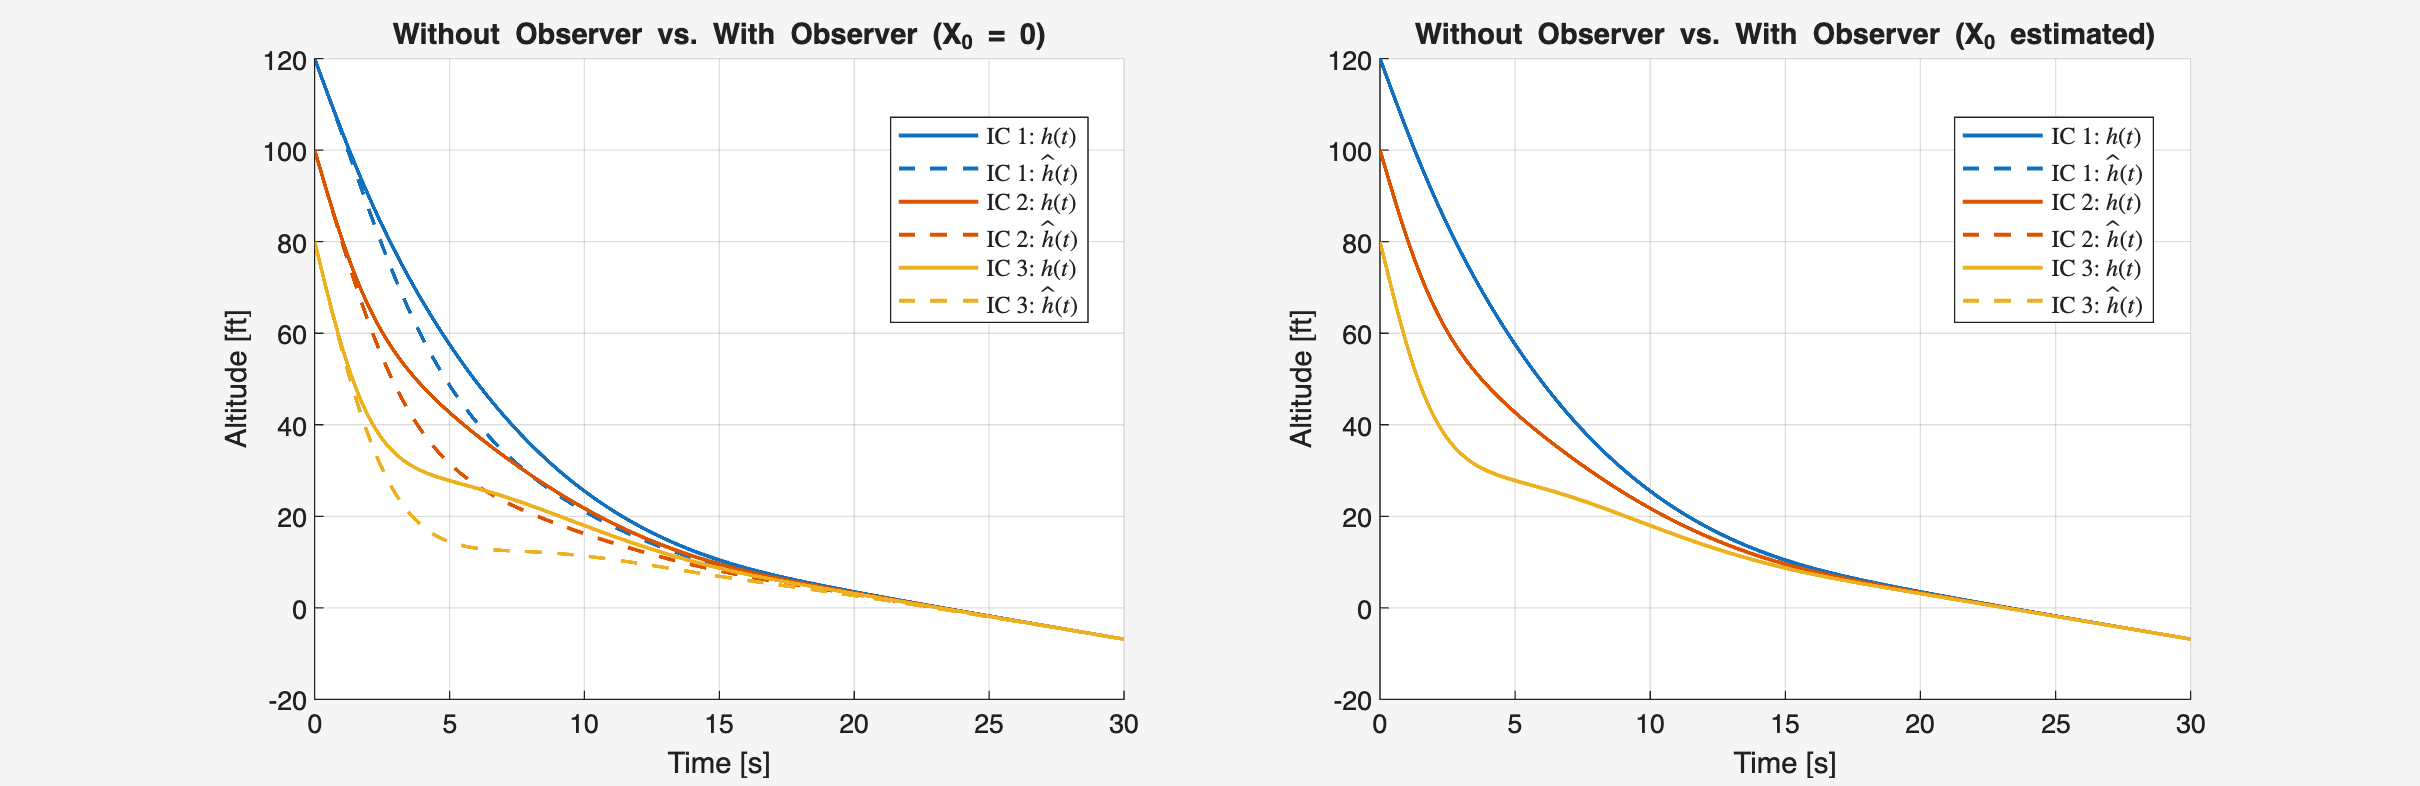

% Comparative plot
f = figure(2);
set(f, 'Visible', 'on')
hold off;
set(f, 'Units','normalized', ...
               'Position', [0.20 0.60 0.8 0.40]); 

subplot(1,2,1);
hold on; grid on;

for i = 1:3
   c = co(i,:);

    plot(t, h_MF(:,i), 'LineWidth', 1.5, 'Color', c, 'LineStyle','-');
    plot(t, h_OBS0(:,i), 'LineWidth', 1.5, 'Color', c, 'LineStyle','--');
end

xlabel('Time [s]');
ylabel('Altitude [ft]');
legend('IC 1: $h(t)$',  'IC 1: $\hat{h}(t)$', ...
       'IC 2: $h(t)$',  'IC 2: $\hat{h}(t)$', ...
       'IC 3: $h(t)$',  'IC 3: $\hat{h}(t)$', ...
       'Location','best', 'Interpreter','latex');
title('Without Observer vs. With Observer (X_0 = 0)')

subplot(1,2,2);
hold on; grid on;

for i = 1:3
   c = co(i,:);

    plot(t, h_MF(:,i), 'LineWidth', 1.5, 'Color', c, 'LineStyle','-');
    plot(t, h_OBSinit(:,i), 'LineWidth', 1.5, 'Color', c, 'LineStyle','--');
end

xlabel('Time [s]');
ylabel('Altitude [ft]');
legend('IC 1: $h(t)$',  'IC 1: $\hat{h}(t)$', ...
       'IC 2: $h(t)$',  'IC 2: $\hat{h}(t)$', ...
       'IC 3: $h(t)$',  'IC 3: $\hat{h}(t)$', ...
       'Location','best', 'Interpreter','latex');
title('Without Observer vs. With Observer (X_0 estimated)')

### 6) Nichols Chart

The Nichols chart shows that the transfer functions of the state-feedback system and the state-feedback system with reduced-order observer are almost identical. This follows from the separation principle; therefore, the observer does not significantly change the stability margins or the shape of the equivalent-loop Nichols diagram.

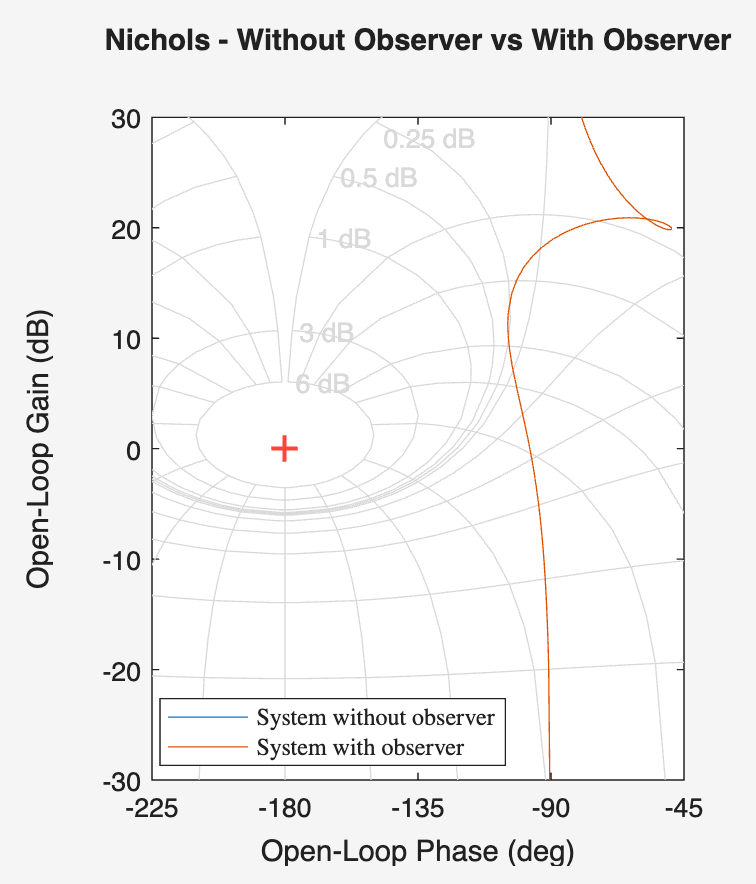

G_SYS = ss(A, B, K, 0);
G_SYS_obs = ss(SYS_F_OL.A, SYS_F_OL.B, K*SYS_F_OL.C, 0);

f = figure(3);
set(f, 'Visible', 'on')
hold on; grid on;

set(f, 'Units','normalized', ...
               'Position', [0.20 0.00 0.25 0.45]);

nichols(G_SYS);
nichols(G_SYS_obs);

grid

xlim([-225 -45]);
ylim([-30 30]);

title('Nichols - Without Observer vs With Observer');
legend('System without observer', ...
       'System with observer', ...
       'Location','Best', 'Interpreter','latex');

### 7) Discretization - Nichols

A linear system has a general solution of the form:


$$x\left(t\right)=\sum_i c_i e^{\lambda_1 t}$$


therefore, the time constant for each real pole is:


$$\tau_i =\frac{1}{\left|\lambda_i \right|}$$


To choose the sampling period, the fastest system dynamics must be considered (the leftmost pole), therefore:

fast_pole = min(real(eig(SYS_F_CL))) % Fastest pole -3.4752

fast_pole = -3.4752

tau_rapido = 1/abs(fast_pole)

tau_rapido = 0.2877

and the sampling period is selected as:


$$T_s <t_{\textrm{rapido}}$$


for this system:


$$T_s <0\ldotp 2877$$


comparing the Nichols chart for different values of $\tau_s$

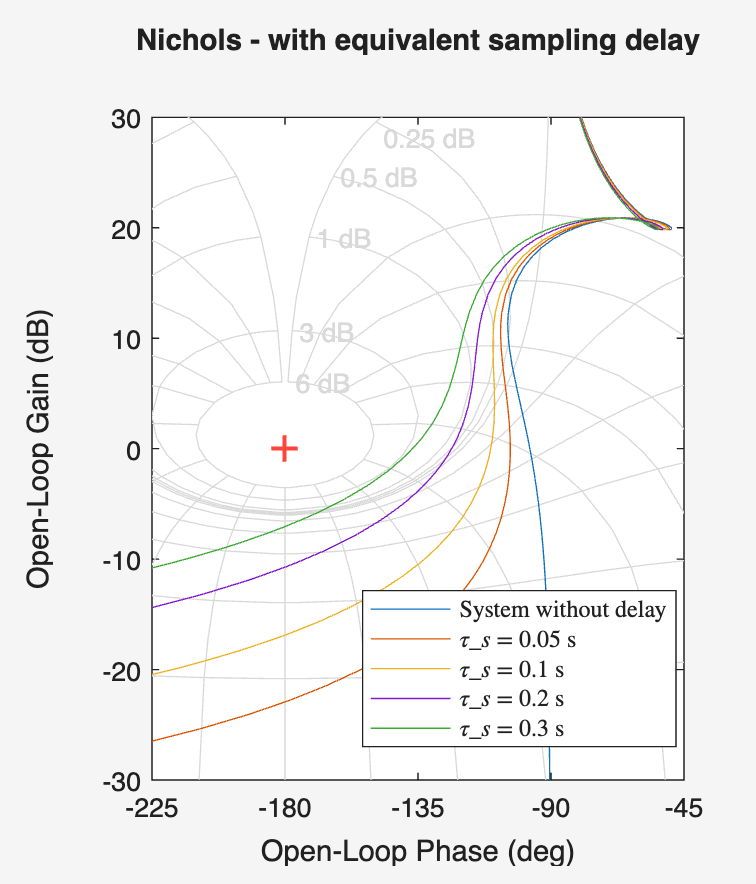

Tvec = [0.05 0.1 0.2 0.3];

f = figure(4);
set(f, 'Visible', 'on')
hold on; grid on;

set(f, 'Units','normalized', ...
               'Position', [0.45 0.00 0.25 0.45]);

% System without discretization
nichols(G_SYS_obs);

% Nichols plot for different Ts values
for k = 1:length(Tvec)
    ts = Tvec(k);
    G_SYS_obs.OutputDelay = ts/2;
    nichols(G_SYS_obs);
end

grid
legend('System without delay', ...
       '$\tau_s$ = 0.05 s', ...
       '$\tau_s$ = 0.1 s', ...
       '$\tau_s$ = 0.2 s', ...
       '$\tau_s$ = 0.3 s', ...
       'Location','Best', 'Interpreter','latex');

xlim([-225 -45]);
ylim([-30 30]);
title('Nichols - with equivalent sampling delay');

For this work, the selected value was


$$\tau_s =0\ldotp 2$$


because it satisfies the criterion of being faster than the fastest pole and, as shown by the chart, preserves adequate gain and phase margins.

### **8) Discretized Controller Simulation**

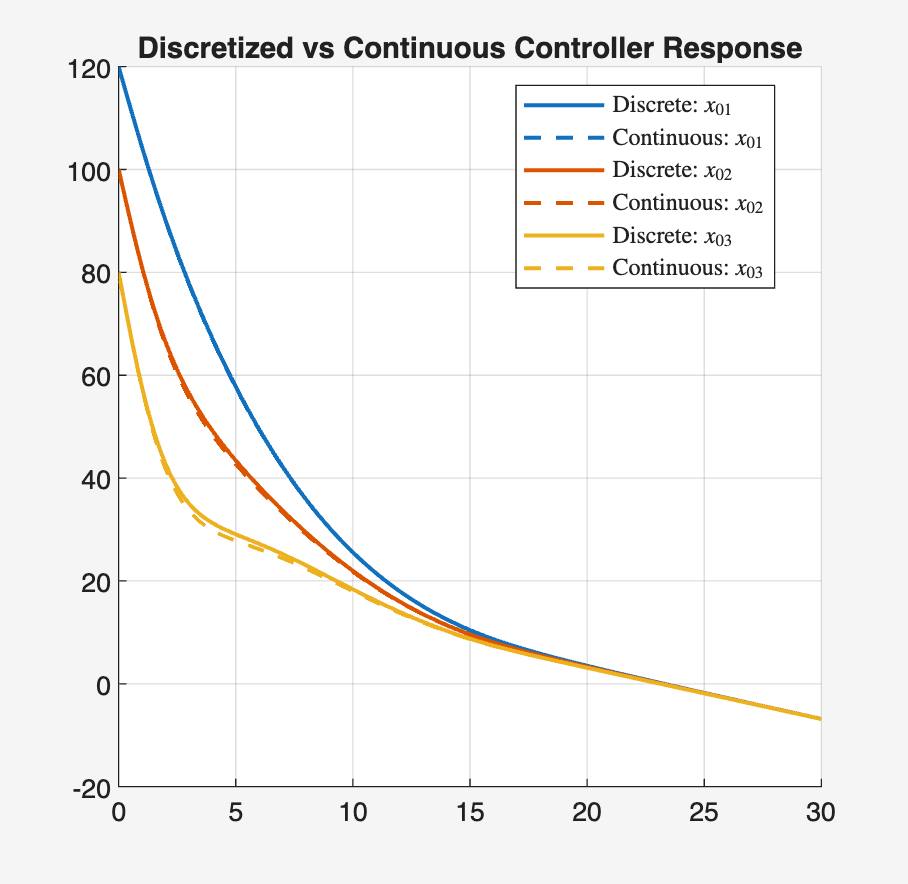

f = figure(5);
set(f, 'Visible', 'on')
hold on; grid on;

set(f, 'Units','normalized', ...
               'Position', [0.70 0.00 0.30 0.45]);

for i = 1:3
    IC_PLANT = X0(i,:);
    IC_X_HAT = 256*X0(i,2);

    % Discrete controller simulation
    simout = sim('DiscreteControllerR2024.slx');
    controle = simout.simulation.signals.values(:,1);
    saida = simout.simulation.signals.values(:,2);
    tempo = simout.simulation.time;

    % Plot the responses for each case
    c = co(i,:);
    plot(tempo, saida, 'LineWidth', 1.5, 'Color', c, 'LineStyle','-');
    plot(t, h_OBSinit(:,i), 'LineWidth', 1.5, 'Color', c, 'LineStyle','--');
end

title(['Discretized vs Continuous Controller Response']);
legend('Discrete: $x_{01}$',  'Continuous: $x_{01}$', ...
       'Discrete: $x_{02}$',  'Continuous: $x_{02}$', ...
       'Discrete: $x_{03}$',  'Continuous: $x_{03}$', ...
       'Location','best', 'Interpreter','latex');